# Raiston's method of 2nd order

clear all, clc

%Initial conditions
t(1) = 0;
x(1) = 1;

% simulation parameters
t_f = 1 ;  
h = .1;  % step size

f = @(x,t) 3*x*(2*t-1)   % Function to be integrated or ODE in RHS 

f = function_handle with value:
    @(x,t)3*x*(2*t-1)


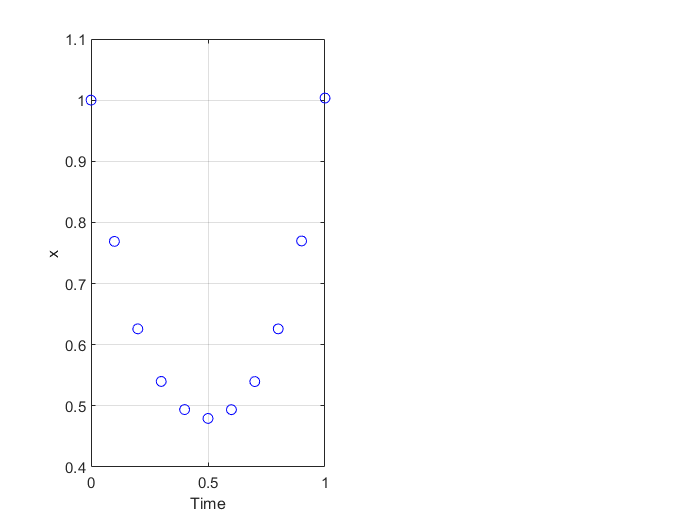


% RK 2 loop

for i= 1:ceil(t_f/h)
    
    %update t
    t(i+1) = t(i) + h;
    
    %update x
    s1 = h*f(x(i),t(i));
    s2 = h*f(x(i) + 2/3*s1, t(i) + 2/3*h);
    
    x(i+1) = x(i) + 1/4*s1 + 3/4*s2;
end

figure(1)
subplot(1,2,1)
plot(t,x, 'bo')
grid on , hold on
xlabel('Time')
ylabel('x')

## classical solution

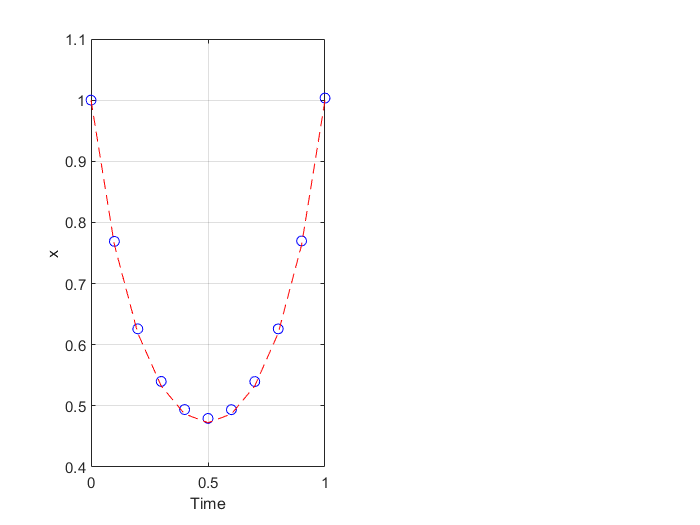

subplot(1,2,1)
g = exp(3.*t.^2 -3*t);
plot(t,g,'r--')